# Dendrite Morphological Neural Network

clear;
% Load Matrix
subject = 'S01';
classes = 6;
location = "C:\Users\jmfig\OneDrive\Escritorio\Matlab_S7\ReadData\";
filename = strcat(location,'\',subject,'\',subject,'x_train.mat');
x_train = load(filename);
filename = strcat(location,'\',subject,'\',subject,'y_train.mat');
y_train = load(filename);
filename = strcat(location,'\',subject,'\',subject,'x_test.mat');
x_test = load(filename);
filename = strcat(location,'\',subject,'\',subject,'y_test.mat');
y_test = load(filename);

x_train = x_train.X_train;
y_train = y_train.y_train;
x_test = x_test.X_test;
y_test = y_test.y_test;

## Convert matrix into requiered matrix form

X = cat(2,x_train,y_train);
M = 1;

## Train DMNN

[weights, classifiedExamples] = trainDMNN(X,M);

## Test DMNN

true = 0;
g1 = zeros(1,48);
g2 = zeros(1,48);
acc = 0;

for i=1:48
    output = predictDMNN(x_test(i,:),weights);
    yfit = find(output);

    if(i <= 8)
        g1(i) = 1;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>8 && i<=16)
        g1(i) = 2;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>16 && i<=24)
        g1(i) = 3;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>24 && i<=32)
        g1(i) = 4;
        g2(i) = yfit;g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>32 && i<=40)
        g1(i) = 5;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    elseif(i>40)
        g1(i) = 6;
        g2(i) = yfit;
        if(yfit == y_test(i,1))
            true = true + 1;
        end
    end

end

acc = true/240;
fprintf('Test accuracy %2f\n',acc)

Test accuracy 0.154167


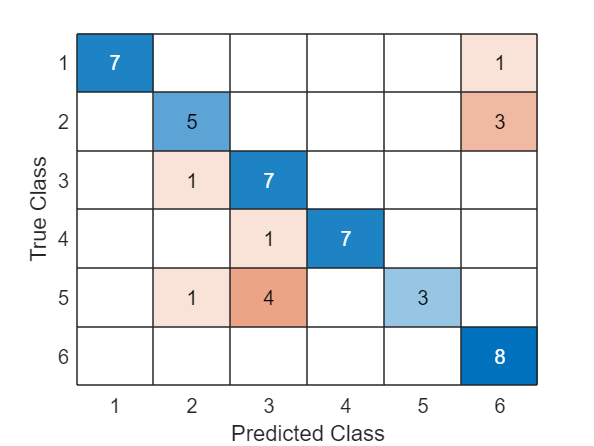

C = confusionmat(g1,g2);

figure;
confusionchart(C)

## Go over every subject folder

clear;

total_subjects = 29;
subject = 0;
M_value = [100, 10, 1, 0.9, 0.8, 0.7, 0.6, 0.5, 0.4, 0.3, 0.2, 0.1, 0.01, 0.001];
path = "C:\Users\jmfig\OneDrive\Escritorio\Matlab_S7\ReadData\";
accuracies = zeros(29,14);
good_acc = [];

for k=1:total_subjects

    % Create paths per subject
    if(subject < 10)
        location = strcat('S0',num2str(subject));
    elseif(subject >= 10)
        location = strcat('S',num2str(subject));
    end

    % Check if location in folder exists
    if exist(location,'dir')

        fprintf(strcat('Subject:', location))

        filename = strcat(path,location,'\',location,'x_train.mat');
        x_train = load(filename);
        filename = strcat(path,location,'\',location,'y_train.mat');
        y_train = load(filename);
        filename = strcat(path,location,'\',location,'x_test.mat');
        x_test = load(filename);
        filename = strcat(path,location,'\',location,'y_test.mat');
        y_test = load(filename);

        x_train = x_train.X_train;
        y_train = y_train.y_train;
        x_test = x_test.X_test;
        y_test = y_test.y_test;

        X = cat(2,x_train,y_train);

        for j=1:length(M_value)
            M = M_value(j);
            [weights, classifiedExamples] = trainDMNN(X,M);
            accuracies(k,j) = Test_Dendrite(x_test,y_test,weights,48);
        end

    end

    subject = subject + 1;
end

Subject:S00

Elapsed time is 0.023795 seconds.
Accuracy 62.500000
Elapsed time is 0.021435 seconds.
Accuracy 62.500000
Elapsed time is 0.024238 seconds.
Accuracy 62.500000
Elapsed time is 0.021701 seconds.
Accuracy 62.500000
Elapsed time is 0.025432 seconds.
Accuracy 62.500000
Elapsed time is 0.027238 seconds.
Accuracy 62.500000
Elapsed time is 0.022316 seconds.
Accuracy 62.500000
Elapsed time is 0.023640 seconds.
Accuracy 62.500000
Elapsed time is 0.028779 seconds.
Accuracy 62.500000
Elapsed time is 0.033377 seconds.
Accuracy 62.500000
Elapsed time is 0.025953 seconds.
Accuracy 62.500000
Elapsed time is 0.024605 seconds.
Accuracy 62.500000
Elapsed time is 0.025534 seconds.
Accuracy 62.500000
Elapsed time is 0.025270 seconds.
Accuracy 62.500000


Subject:S01

Elapsed time is 0.029917 seconds.
Accuracy 77.080000
Elapsed time is 0.025797 seconds.
Accuracy 77.080000
Elapsed time is 0.029292 seconds.
Accuracy 77.080000
Elapsed time is 0.032533 seconds.
Accuracy 77.080000
Elapsed time is 0.029561 seconds.
Accuracy 77.080000
Elapsed time is 0.027759 seconds.
Accuracy 77.080000
Elapsed time is 0.028165 seconds.
Accuracy 77.080000
Elapsed time is 0.026964 seconds.
Accuracy 77.080000
Elapsed time is 0.029157 seconds.
Accuracy 77.080000
Elapsed time is 0.026057 seconds.
Accuracy 77.080000
Elapsed time is 0.027738 seconds.
Accuracy 77.080000
Elapsed time is 0.028943 seconds.
Accuracy 77.080000
Elapsed time is 0.025088 seconds.
Accuracy 77.080000
Elapsed time is 0.026511 seconds.
Accuracy 77.080000


Subject:S02

Elapsed time is 0.023966 seconds.
Accuracy 85.420000
Elapsed time is 0.026716 seconds.
Accuracy 85.420000
Elapsed time is 0.025162 seconds.
Accuracy 85.420000
Elapsed time is 0.024343 seconds.
Accuracy 85.420000
Elapsed time is 0.027258 seconds.
Accuracy 85.420000
Elapsed time is 0.025930 seconds.
Accuracy 85.420000
Elapsed time is 0.026733 seconds.
Accuracy 85.420000
Elapsed time is 0.022349 seconds.
Accuracy 85.420000
Elapsed time is 0.027364 seconds.
Accuracy 85.420000
Elapsed time is 0.027580 seconds.
Accuracy 85.420000
Elapsed time is 0.027847 seconds.
Accuracy 85.420000
Elapsed time is 0.030461 seconds.
Accuracy 85.420000
Elapsed time is 0.033209 seconds.
Accuracy 85.420000
Elapsed time is 0.031651 seconds.
Accuracy 85.420000


Subject:S03

Elapsed time is 0.028828 seconds.
Accuracy 58.330000
Elapsed time is 0.030447 seconds.
Accuracy 58.330000
Elapsed time is 0.028796 seconds.
Accuracy 58.330000
Elapsed time is 0.026221 seconds.
Accuracy 58.330000
Elapsed time is 0.028741 seconds.
Accuracy 58.330000
Elapsed time is 0.028721 seconds.
Accuracy 58.330000
Elapsed time is 0.026192 seconds.
Accuracy 58.330000
Elapsed time is 0.027466 seconds.
Accuracy 58.330000
Elapsed time is 0.025355 seconds.
Accuracy 58.330000
Elapsed time is 0.031807 seconds.
Accuracy 58.330000
Elapsed time is 0.029004 seconds.
Accuracy 58.330000
Elapsed time is 0.028045 seconds.
Accuracy 58.330000
Elapsed time is 0.028872 seconds.
Accuracy 58.330000
Elapsed time is 0.027281 seconds.
Accuracy 58.330000


Subject:S04

Elapsed time is 0.030935 seconds.
Accuracy 66.670000
Elapsed time is 0.030913 seconds.
Accuracy 66.670000
Elapsed time is 0.028662 seconds.
Accuracy 66.670000
Elapsed time is 0.029809 seconds.
Accuracy 66.670000
Elapsed time is 0.029615 seconds.
Accuracy 66.670000
Elapsed time is 0.029169 seconds.
Accuracy 66.670000
Elapsed time is 0.028724 seconds.
Accuracy 66.670000
Elapsed time is 0.030305 seconds.
Accuracy 66.670000
Elapsed time is 0.029016 seconds.
Accuracy 66.670000
Elapsed time is 0.026435 seconds.
Accuracy 66.670000
Elapsed time is 0.027126 seconds.
Accuracy 66.670000
Elapsed time is 0.029787 seconds.
Accuracy 66.670000
Elapsed time is 0.029576 seconds.
Accuracy 66.670000
Elapsed time is 0.030829 seconds.
Accuracy 66.670000


Subject:S05

Elapsed time is 0.023598 seconds.
Accuracy 18.750000
Elapsed time is 0.022996 seconds.
Accuracy 18.750000
Elapsed time is 0.021460 seconds.
Accuracy 18.750000
Elapsed time is 0.028816 seconds.
Accuracy 18.750000
Elapsed time is 0.022180 seconds.
Accuracy 18.750000
Elapsed time is 0.018818 seconds.
Accuracy 18.750000
Elapsed time is 0.020763 seconds.
Accuracy 18.750000
Elapsed time is 0.022191 seconds.
Accuracy 18.750000
Elapsed time is 0.028596 seconds.
Accuracy 18.750000
Elapsed time is 0.025865 seconds.
Accuracy 18.750000
Elapsed time is 0.025153 seconds.
Accuracy 18.750000
Elapsed time is 0.025468 seconds.
Accuracy 18.750000
Elapsed time is 0.024631 seconds.
Accuracy 18.750000
Elapsed time is 0.022842 seconds.
Accuracy 18.750000


Subject:S06

Elapsed time is 0.026123 seconds.
Accuracy 72.920000
Elapsed time is 0.027719 seconds.
Accuracy 72.920000
Elapsed time is 0.025885 seconds.
Accuracy 72.920000
Elapsed time is 0.026575 seconds.
Accuracy 72.920000
Elapsed time is 0.026638 seconds.
Accuracy 72.920000
Elapsed time is 0.027807 seconds.
Accuracy 72.920000
Elapsed time is 0.027431 seconds.
Accuracy 72.920000
Elapsed time is 0.026752 seconds.
Accuracy 72.920000
Elapsed time is 0.026460 seconds.
Accuracy 72.920000
Elapsed time is 0.027353 seconds.
Accuracy 72.920000
Elapsed time is 0.027529 seconds.
Accuracy 72.920000
Elapsed time is 0.031696 seconds.
Accuracy 72.920000
Elapsed time is 0.028391 seconds.
Accuracy 72.920000
Elapsed time is 0.028158 seconds.
Accuracy 72.920000


Subject:S07

Elapsed time is 0.027149 seconds.
Accuracy 91.670000
Elapsed time is 0.027299 seconds.
Accuracy 91.670000
Elapsed time is 0.024344 seconds.
Accuracy 91.670000
Elapsed time is 0.025870 seconds.
Accuracy 91.670000
Elapsed time is 0.025728 seconds.
Accuracy 91.670000
Elapsed time is 0.026243 seconds.
Accuracy 91.670000
Elapsed time is 0.026968 seconds.
Accuracy 91.670000
Elapsed time is 0.024147 seconds.
Accuracy 91.670000
Elapsed time is 0.028292 seconds.
Accuracy 91.670000
Elapsed time is 0.027487 seconds.
Accuracy 91.670000
Elapsed time is 0.030018 seconds.
Accuracy 91.670000
Elapsed time is 0.028288 seconds.
Accuracy 91.670000
Elapsed time is 0.029165 seconds.
Accuracy 91.670000
Elapsed time is 0.030560 seconds.
Accuracy 91.670000


Subject:S08

Elapsed time is 0.028415 seconds.
Accuracy 91.670000
Elapsed time is 0.025603 seconds.
Accuracy 91.670000
Elapsed time is 0.027898 seconds.
Accuracy 91.670000
Elapsed time is 0.029007 seconds.
Accuracy 91.670000
Elapsed time is 0.039163 seconds.
Accuracy 91.670000
Elapsed time is 0.025876 seconds.
Accuracy 91.670000
Elapsed time is 0.030280 seconds.
Accuracy 91.670000
Elapsed time is 0.026754 seconds.
Accuracy 91.670000
Elapsed time is 0.028489 seconds.
Accuracy 91.670000
Elapsed time is 0.031319 seconds.
Accuracy 91.670000
Elapsed time is 0.030284 seconds.
Accuracy 91.670000
Elapsed time is 0.032138 seconds.
Accuracy 91.670000
Elapsed time is 0.029777 seconds.
Accuracy 91.670000
Elapsed time is 0.029881 seconds.
Accuracy 91.670000


Subject:S09

Elapsed time is 0.031225 seconds.
Accuracy 75.000000
Elapsed time is 0.029811 seconds.
Accuracy 75.000000
Elapsed time is 0.027700 seconds.
Accuracy 75.000000
Elapsed time is 0.028896 seconds.
Accuracy 75.000000
Elapsed time is 0.030914 seconds.
Accuracy 75.000000
Elapsed time is 0.028679 seconds.
Accuracy 75.000000
Elapsed time is 0.028647 seconds.
Accuracy 75.000000
Elapsed time is 0.028464 seconds.
Accuracy 75.000000
Elapsed time is 0.032070 seconds.
Accuracy 75.000000
Elapsed time is 0.030937 seconds.
Accuracy 75.000000
Elapsed time is 0.029358 seconds.
Accuracy 75.000000
Elapsed time is 0.030483 seconds.
Accuracy 75.000000
Elapsed time is 0.033541 seconds.
Accuracy 75.000000
Elapsed time is 0.030096 seconds.
Accuracy 75.000000


Subject:S10

Elapsed time is 0.029983 seconds.
Accuracy 85.420000
Elapsed time is 0.027267 seconds.
Accuracy 85.420000
Elapsed time is 0.029177 seconds.
Accuracy 85.420000
Elapsed time is 0.029918 seconds.
Accuracy 85.420000
Elapsed time is 0.027995 seconds.
Accuracy 85.420000
Elapsed time is 0.030906 seconds.
Accuracy 85.420000
Elapsed time is 0.030220 seconds.
Accuracy 85.420000
Elapsed time is 0.032208 seconds.
Accuracy 85.420000
Elapsed time is 0.032087 seconds.
Accuracy 85.420000
Elapsed time is 0.033059 seconds.
Accuracy 85.420000
Elapsed time is 0.032467 seconds.
Accuracy 85.420000
Elapsed time is 0.032898 seconds.
Accuracy 85.420000
Elapsed time is 0.031049 seconds.
Accuracy 85.420000
Elapsed time is 0.028984 seconds.
Accuracy 85.420000


Subject:S11

Elapsed time is 0.027154 seconds.
Accuracy 100.000000
Elapsed time is 0.028351 seconds.
Accuracy 100.000000
Elapsed time is 0.027815 seconds.
Accuracy 100.000000
Elapsed time is 0.030272 seconds.
Accuracy 100.000000
Elapsed time is 0.027010 seconds.
Accuracy 100.000000
Elapsed time is 0.029874 seconds.
Accuracy 100.000000
Elapsed time is 0.028432 seconds.
Accuracy 100.000000
Elapsed time is 0.028260 seconds.
Accuracy 100.000000
Elapsed time is 0.029586 seconds.
Accuracy 100.000000
Elapsed time is 0.031986 seconds.
Accuracy 100.000000
Elapsed time is 0.031598 seconds.
Accuracy 100.000000
Elapsed time is 0.028890 seconds.
Accuracy 100.000000
Elapsed time is 0.028205 seconds.
Accuracy 100.000000
Elapsed time is 0.029766 seconds.
Accuracy 100.000000


Subject:S12

Elapsed time is 0.022819 seconds.
Accuracy 60.420000
Elapsed time is 0.028212 seconds.
Accuracy 60.420000
Elapsed time is 0.026578 seconds.
Accuracy 60.420000
Elapsed time is 0.026089 seconds.
Accuracy 60.420000
Elapsed time is 0.024005 seconds.
Accuracy 60.420000
Elapsed time is 0.022666 seconds.
Accuracy 60.420000
Elapsed time is 0.024311 seconds.
Accuracy 60.420000
Elapsed time is 0.026723 seconds.
Accuracy 60.420000
Elapsed time is 0.030343 seconds.
Accuracy 60.420000
Elapsed time is 0.032502 seconds.
Accuracy 60.420000
Elapsed time is 0.029237 seconds.
Accuracy 60.420000
Elapsed time is 0.031214 seconds.
Accuracy 60.420000
Elapsed time is 0.029709 seconds.
Accuracy 60.420000
Elapsed time is 0.025594 seconds.
Accuracy 60.420000


Subject:S13

Elapsed time is 0.020414 seconds.
Accuracy 52.080000
Elapsed time is 0.020493 seconds.
Accuracy 52.080000
Elapsed time is 0.019309 seconds.
Accuracy 52.080000
Elapsed time is 0.023648 seconds.
Accuracy 52.080000
Elapsed time is 0.020796 seconds.
Accuracy 52.080000
Elapsed time is 0.019437 seconds.
Accuracy 52.080000
Elapsed time is 0.020231 seconds.
Accuracy 52.080000
Elapsed time is 0.021987 seconds.
Accuracy 52.080000
Elapsed time is 0.026707 seconds.
Accuracy 52.080000
Elapsed time is 0.028839 seconds.
Accuracy 52.080000
Elapsed time is 0.024761 seconds.
Accuracy 52.080000
Elapsed time is 0.030903 seconds.
Accuracy 52.080000
Elapsed time is 0.024781 seconds.
Accuracy 52.080000
Elapsed time is 0.025890 seconds.
Accuracy 52.080000


Subject:S14

Elapsed time is 0.030313 seconds.
Accuracy 95.830000
Elapsed time is 0.030785 seconds.
Accuracy 95.830000
Elapsed time is 0.031667 seconds.
Accuracy 95.830000
Elapsed time is 0.030559 seconds.
Accuracy 95.830000
Elapsed time is 0.030515 seconds.
Accuracy 95.830000
Elapsed time is 0.039288 seconds.
Accuracy 95.830000
Elapsed time is 0.029636 seconds.
Accuracy 95.830000
Elapsed time is 0.032570 seconds.
Accuracy 95.830000
Elapsed time is 0.028154 seconds.
Accuracy 95.830000
Elapsed time is 0.028515 seconds.
Accuracy 95.830000
Elapsed time is 0.025756 seconds.
Accuracy 95.830000
Elapsed time is 0.029282 seconds.
Accuracy 95.830000
Elapsed time is 0.031395 seconds.
Accuracy 95.830000
Elapsed time is 0.030989 seconds.
Accuracy 95.830000


Subject:S15

Elapsed time is 0.028251 seconds.
Accuracy 91.670000
Elapsed time is 0.024635 seconds.
Accuracy 91.670000
Elapsed time is 0.028619 seconds.
Accuracy 91.670000
Elapsed time is 0.026406 seconds.
Accuracy 91.670000
Elapsed time is 0.029916 seconds.
Accuracy 91.670000
Elapsed time is 0.027309 seconds.
Accuracy 91.670000
Elapsed time is 0.026563 seconds.
Accuracy 91.670000
Elapsed time is 0.029667 seconds.
Accuracy 91.670000
Elapsed time is 0.032741 seconds.
Accuracy 91.670000
Elapsed time is 0.029806 seconds.
Accuracy 91.670000
Elapsed time is 0.027815 seconds.
Accuracy 91.670000
Elapsed time is 0.035270 seconds.
Accuracy 91.670000
Elapsed time is 0.025625 seconds.
Accuracy 91.670000
Elapsed time is 0.029197 seconds.
Accuracy 91.670000


Subject:S16

Elapsed time is 0.029523 seconds.
Accuracy 91.670000
Elapsed time is 0.029039 seconds.
Accuracy 91.670000
Elapsed time is 0.031113 seconds.
Accuracy 91.670000
Elapsed time is 0.029297 seconds.
Accuracy 91.670000
Elapsed time is 0.029115 seconds.
Accuracy 91.670000
Elapsed time is 0.028580 seconds.
Accuracy 91.670000
Elapsed time is 0.032465 seconds.
Accuracy 91.670000
Elapsed time is 0.030183 seconds.
Accuracy 91.670000
Elapsed time is 0.027678 seconds.
Accuracy 91.670000
Elapsed time is 0.029251 seconds.
Accuracy 91.670000
Elapsed time is 0.028833 seconds.
Accuracy 91.670000
Elapsed time is 0.032134 seconds.
Accuracy 91.670000
Elapsed time is 0.034844 seconds.
Accuracy 91.670000
Elapsed time is 0.029788 seconds.
Accuracy 91.670000


Subject:S17

Elapsed time is 0.027377 seconds.
Accuracy 91.670000
Elapsed time is 0.028816 seconds.
Accuracy 91.670000
Elapsed time is 0.032539 seconds.
Accuracy 91.670000
Elapsed time is 0.026592 seconds.
Accuracy 91.670000
Elapsed time is 0.029815 seconds.
Accuracy 91.670000
Elapsed time is 0.029659 seconds.
Accuracy 91.670000
Elapsed time is 0.029547 seconds.
Accuracy 91.670000
Elapsed time is 0.029462 seconds.
Accuracy 91.670000
Elapsed time is 0.031060 seconds.
Accuracy 91.670000
Elapsed time is 0.028677 seconds.
Accuracy 91.670000
Elapsed time is 0.025263 seconds.
Accuracy 91.670000
Elapsed time is 0.030221 seconds.
Accuracy 91.670000
Elapsed time is 0.033898 seconds.
Accuracy 91.670000
Elapsed time is 0.025669 seconds.
Accuracy 91.670000


Subject:S18

Elapsed time is 0.028568 seconds.
Accuracy 68.750000
Elapsed time is 0.031622 seconds.
Accuracy 68.750000
Elapsed time is 0.030392 seconds.
Accuracy 68.750000
Elapsed time is 0.032655 seconds.
Accuracy 68.750000
Elapsed time is 0.030529 seconds.
Accuracy 68.750000
Elapsed time is 0.029881 seconds.
Accuracy 68.750000
Elapsed time is 0.033527 seconds.
Accuracy 68.750000
Elapsed time is 0.032785 seconds.
Accuracy 68.750000
Elapsed time is 0.031367 seconds.
Accuracy 68.750000
Elapsed time is 0.030131 seconds.
Accuracy 68.750000
Elapsed time is 0.026337 seconds.
Accuracy 68.750000
Elapsed time is 0.032262 seconds.
Accuracy 68.750000
Elapsed time is 0.032672 seconds.
Accuracy 68.750000
Elapsed time is 0.032093 seconds.
Accuracy 68.750000


Subject:S19

Elapsed time is 0.018828 seconds.
Accuracy 68.750000
Elapsed time is 0.018655 seconds.
Accuracy 68.750000
Elapsed time is 0.017993 seconds.
Accuracy 68.750000
Elapsed time is 0.017781 seconds.
Accuracy 68.750000
Elapsed time is 0.017663 seconds.
Accuracy 68.750000
Elapsed time is 0.018915 seconds.
Accuracy 68.750000
Elapsed time is 0.018414 seconds.
Accuracy 68.750000
Elapsed time is 0.019545 seconds.
Accuracy 68.750000
Elapsed time is 0.022189 seconds.
Accuracy 68.750000
Elapsed time is 0.025979 seconds.
Accuracy 68.750000
Elapsed time is 0.023801 seconds.
Accuracy 68.750000
Elapsed time is 0.027892 seconds.
Accuracy 68.750000
Elapsed time is 0.023511 seconds.
Accuracy 68.750000
Elapsed time is 0.022287 seconds.
Accuracy 68.750000


Subject:S20

Elapsed time is 0.021993 seconds.
Accuracy 87.500000
Elapsed time is 0.022791 seconds.
Accuracy 87.500000
Elapsed time is 0.021901 seconds.
Accuracy 87.500000
Elapsed time is 0.025430 seconds.
Accuracy 87.500000
Elapsed time is 0.026370 seconds.
Accuracy 87.500000
Elapsed time is 0.021220 seconds.
Accuracy 87.500000
Elapsed time is 0.021490 seconds.
Accuracy 87.500000
Elapsed time is 0.022929 seconds.
Accuracy 87.500000
Elapsed time is 0.027432 seconds.
Accuracy 87.500000
Elapsed time is 0.024745 seconds.
Accuracy 87.500000
Elapsed time is 0.026450 seconds.
Accuracy 87.500000
Elapsed time is 0.029600 seconds.
Accuracy 87.500000
Elapsed time is 0.028511 seconds.
Accuracy 87.500000
Elapsed time is 0.029234 seconds.
Accuracy 87.500000


Subject:S21

Elapsed time is 0.020602 seconds.
Accuracy 75.000000
Elapsed time is 0.026658 seconds.
Accuracy 75.000000
Elapsed time is 0.021147 seconds.
Accuracy 75.000000
Elapsed time is 0.021058 seconds.
Accuracy 75.000000
Elapsed time is 0.022054 seconds.
Accuracy 75.000000
Elapsed time is 0.026813 seconds.
Accuracy 75.000000
Elapsed time is 0.021205 seconds.
Accuracy 75.000000
Elapsed time is 0.021277 seconds.
Accuracy 75.000000
Elapsed time is 0.027437 seconds.
Accuracy 75.000000
Elapsed time is 0.029013 seconds.
Accuracy 75.000000
Elapsed time is 0.028631 seconds.
Accuracy 75.000000
Elapsed time is 0.031152 seconds.
Accuracy 75.000000
Elapsed time is 0.027287 seconds.
Accuracy 75.000000
Elapsed time is 0.030914 seconds.
Accuracy 75.000000


Subject:S22

Elapsed time is 0.029447 seconds.
Accuracy 50.000000
Elapsed time is 0.029222 seconds.
Accuracy 50.000000
Elapsed time is 0.033610 seconds.
Accuracy 50.000000
Elapsed time is 0.035259 seconds.
Accuracy 50.000000
Elapsed time is 0.032258 seconds.
Accuracy 50.000000
Elapsed time is 0.028196 seconds.
Accuracy 50.000000
Elapsed time is 0.029785 seconds.
Accuracy 50.000000
Elapsed time is 0.031095 seconds.
Accuracy 50.000000
Elapsed time is 0.033834 seconds.
Accuracy 50.000000
Elapsed time is 0.028102 seconds.
Accuracy 50.000000
Elapsed time is 0.029287 seconds.
Accuracy 50.000000
Elapsed time is 0.028659 seconds.
Accuracy 50.000000
Elapsed time is 0.029741 seconds.
Accuracy 50.000000
Elapsed time is 0.029343 seconds.
Accuracy 50.000000


Subject:S23

Elapsed time is 0.025103 seconds.
Accuracy 72.920000
Elapsed time is 0.026870 seconds.
Accuracy 72.920000
Elapsed time is 0.024055 seconds.
Accuracy 72.920000
Elapsed time is 0.027787 seconds.
Accuracy 72.920000
Elapsed time is 0.027362 seconds.
Accuracy 72.920000
Elapsed time is 0.026347 seconds.
Accuracy 72.920000
Elapsed time is 0.027398 seconds.
Accuracy 72.920000
Elapsed time is 0.025853 seconds.
Accuracy 72.920000
Elapsed time is 0.024148 seconds.
Accuracy 72.920000
Elapsed time is 0.028080 seconds.
Accuracy 72.920000
Elapsed time is 0.027595 seconds.
Accuracy 72.920000
Elapsed time is 0.028401 seconds.
Accuracy 72.920000
Elapsed time is 0.029745 seconds.
Accuracy 72.920000
Elapsed time is 0.024083 seconds.
Accuracy 72.920000


Subject:S24

Elapsed time is 0.021730 seconds.
Accuracy 45.830000
Elapsed time is 0.022113 seconds.
Accuracy 45.830000
Elapsed time is 0.020799 seconds.
Accuracy 45.830000
Elapsed time is 0.019420 seconds.
Accuracy 45.830000
Elapsed time is 0.021731 seconds.
Accuracy 45.830000
Elapsed time is 0.020632 seconds.
Accuracy 45.830000
Elapsed time is 0.021060 seconds.
Accuracy 45.830000
Elapsed time is 0.019629 seconds.
Accuracy 45.830000
Elapsed time is 0.024950 seconds.
Accuracy 45.830000
Elapsed time is 0.026906 seconds.
Accuracy 45.830000
Elapsed time is 0.023338 seconds.
Accuracy 45.830000
Elapsed time is 0.027328 seconds.
Accuracy 45.830000
Elapsed time is 0.025965 seconds.
Accuracy 45.830000
Elapsed time is 0.030163 seconds.
Accuracy 45.830000


Subject:S25

Elapsed time is 0.029450 seconds.
Accuracy 50.000000
Elapsed time is 0.032828 seconds.
Accuracy 50.000000
Elapsed time is 0.028890 seconds.
Accuracy 50.000000
Elapsed time is 0.031822 seconds.
Accuracy 50.000000
Elapsed time is 0.032956 seconds.
Accuracy 50.000000
Elapsed time is 0.031209 seconds.
Accuracy 50.000000
Elapsed time is 0.030330 seconds.
Accuracy 50.000000
Elapsed time is 0.025892 seconds.
Accuracy 50.000000
Elapsed time is 0.030606 seconds.
Accuracy 50.000000
Elapsed time is 0.030858 seconds.
Accuracy 50.000000
Elapsed time is 0.029365 seconds.
Accuracy 50.000000
Elapsed time is 0.038652 seconds.
Accuracy 50.000000
Elapsed time is 0.032565 seconds.
Accuracy 50.000000
Elapsed time is 0.032083 seconds.
Accuracy 50.000000


Subject:S26

Elapsed time is 0.030940 seconds.
Accuracy 72.920000
Elapsed time is 0.030327 seconds.
Accuracy 72.920000
Elapsed time is 0.034774 seconds.
Accuracy 72.920000
Elapsed time is 0.029698 seconds.
Accuracy 72.920000
Elapsed time is 0.033330 seconds.
Accuracy 72.920000
Elapsed time is 0.034470 seconds.
Accuracy 70.830000
Elapsed time is 0.029627 seconds.
Accuracy 72.920000
Elapsed time is 0.031498 seconds.
Accuracy 72.920000
Elapsed time is 0.030716 seconds.
Accuracy 72.920000
Elapsed time is 0.031347 seconds.
Accuracy 72.920000
Elapsed time is 0.038158 seconds.
Accuracy 72.920000
Elapsed time is 0.031738 seconds.
Accuracy 72.920000
Elapsed time is 0.034320 seconds.
Accuracy 72.920000
Elapsed time is 0.030256 seconds.
Accuracy 72.920000


Subject:S27

Elapsed time is 0.026767 seconds.
Accuracy 75.000000
Elapsed time is 0.029566 seconds.
Accuracy 75.000000
Elapsed time is 0.029295 seconds.
Accuracy 75.000000
Elapsed time is 0.027629 seconds.
Accuracy 75.000000
Elapsed time is 0.027382 seconds.
Accuracy 75.000000
Elapsed time is 0.033171 seconds.
Accuracy 75.000000
Elapsed time is 0.034922 seconds.
Accuracy 75.000000
Elapsed time is 0.028874 seconds.
Accuracy 75.000000
Elapsed time is 0.031053 seconds.
Accuracy 75.000000
Elapsed time is 0.029354 seconds.
Accuracy 75.000000
Elapsed time is 0.028624 seconds.
Accuracy 75.000000
Elapsed time is 0.027748 seconds.
Accuracy 75.000000
Elapsed time is 0.028307 seconds.
Accuracy 75.000000
Elapsed time is 0.029697 seconds.
Accuracy 75.000000


Subject:S28

Elapsed time is 0.029756 seconds.
Accuracy 70.830000
Elapsed time is 0.029806 seconds.
Accuracy 70.830000
Elapsed time is 0.027817 seconds.
Accuracy 70.830000
Elapsed time is 0.031452 seconds.
Accuracy 75.000000
Elapsed time is 0.030554 seconds.
Accuracy 75.000000
Elapsed time is 0.030093 seconds.
Accuracy 70.830000
Elapsed time is 0.028924 seconds.
Accuracy 70.830000
Elapsed time is 0.030353 seconds.
Accuracy 70.830000
Elapsed time is 0.028371 seconds.
Accuracy 70.830000
Elapsed time is 0.029104 seconds.
Accuracy 70.830000
Elapsed time is 0.028533 seconds.
Accuracy 70.830000
Elapsed time is 0.028417 seconds.
Accuracy 70.830000
Elapsed time is 0.030804 seconds.
Accuracy 70.830000
Elapsed time is 0.027992 seconds.
Accuracy 70.830000


Check for good subjects

good_acc = [];
for i=1:total_subjects
    if(accuracies(i,1) > 80)
        good_acc(end+1) = i-1; 
    end
end

Write in XLSX 

writematrix(accuracies,'Dendrite_Test.xlsx');